# Heart Attack Project Code

## Feature Analysis and Plots

h_data = readmatrix("heart.csv"); 
data = h_data

data =    63.0000    1.0000    3.0000  145.0000  233.0000    1.0000         0  150.0000         0    2.3000         0         0    1.0000    1.0000
   37.0000    1.0000    2.0000  130.0000  250.0000         0    1.0000  187.0000         0    3.5000         0         0    2.0000    1.0000
   41.0000         0    1.0000  130.0000  204.0000         0         0  172.0000         0    1.4000    2.0000         0    2.0000    1.0000
   56.0000    1.0000    1.0000  120.0000  236.0000         0    1.0000  178.0000         0    0.8000    2.0000         0    2.0000    1.0000
   57.0000         0         0  120.0000  354.0000         0    1.0000  163.0000    1.0000    0.6000    2.0000         0    2.0000    1.0000
   57.0000    1.0000         0  140.0000  192.0000         0    1.0000  148.0000         0    0.4000    1.0000         0    1.0000    1.0000
   56.0000         0    1.0000  140.0000  294.0000         0         0  153.0000         0    1.3000    1.0000         0    2.0000    1.0000
   44.


% 5 random examples and all the feature names 
head(h_data, 5)

   63.0000    1.0000    3.0000  145.0000  233.0000    1.0000         0  150.0000         0    2.3000         0         0    1.0000    1.0000
   37.0000    1.0000    2.0000  130.0000  250.0000         0    1.0000  187.0000         0    3.5000         0         0    2.0000    1.0000
   41.0000         0    1.0000  130.0000  204.0000         0         0  172.0000         0    1.4000    2.0000         0    2.0000    1.0000
   56.0000    1.0000    1.0000  120.0000  236.0000         0    1.0000  178.0000         0    0.8000    2.0000         0    2.0000    1.0000
   57.0000         0         0  120.0000  354.0000         0    1.0000  163.0000    1.0000    0.6000    2.0000         0    2.0000    1.0000




% DATA SIZE: (303 x 14)

m = 14;
% columnNames = data.Properties.VariableNames;
% commenting out for now
columnNames = {'age', 'sex', 'cp', 'trtbps', 'chol', 'fbs', 'restecg', 'thalachh', 'exng', 'oldpeak', 'slp', 'caa', 'thall', 'output'};



% Missing Values
missingCounts = sum(ismissing(data));
disp('Missing Values per Column:');

Missing Values per Column:


for i = 1:length(columnNames)
   fprintf('%-15s: %d\n', columnNames{i}, missingCounts(i));
end

age            : 0
sex            : 0
cp             : 0
trtbps         : 0
chol           : 0
fbs            : 0
restecg        : 0
thalachh       : 0
exng           : 0
oldpeak        : 0
slp            : 0
caa            : 0
thall          : 0
output         : 0



% Feature Distribution
% This  may take a while to run
for i = 1 : m
    plotHistogram(h_data(:, i), columnNames{i})
end

disp('Histograms Complete!')

Histograms Complete!



% Correlation Matrix

% Feature Scaling

## Initializing Data

% Initialize Data
X = h_data(:, 1:13);
[m,n] = size(X);
X = [ones(m,1), X];
y = h_data(:,end);

% Train Test Split
seed=41470;
rng(seed);
test_percent = 0.2;
cv = cvpartition(m,'Holdout',test_percent); % Nonstratified partition
idx = cv.test;

X_train = X(cv.training,:);
y_train = y(cv.training, :);
X_test = X(cv.test, :);
y_test = y(cv.test, :);


## Unregularized Logistic Regression Model

%======================Log Unreg Gradient Descent========================%

% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, cost] = ...
    fminunc(@(t)(costFunctionUnReg(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.348904



fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 3.450473 
 -0.004908 
 -1.758188 
 0.859852 
 -0.019477 
 -0.004630 
 0.034890 
 0.466289 
 0.023211 
 -0.979976 
 -0.540281 
 0.579272 
 -0.773347 
 -0.900430 


% Accuracy Checking

p_train = predict(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 84.362140



p_test = predict(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 88.333333


## Regularized Logistic Regression Model

%======================Log Reg Gradient Descent========================%


% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set regularization parameter lambda
lambda = 5;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
        fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.348904


fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 1.599548 
 -0.000642 
 -0.935712 
 0.709054 
 -0.016956 
 -0.003029 
 -0.010316 
 0.296360 
 0.024145 
 -0.583540 
 -0.510406 
 0.357924 
 -0.633101 
 -0.691405 


%===================================================================%


% Accuracy Checking

p_train = predict(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 85.596708


p_test = predict(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 90.000000


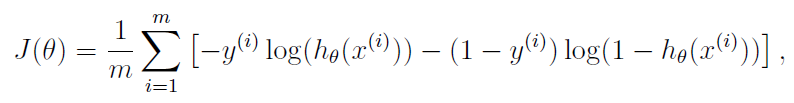

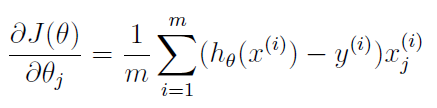

%=======================================LOG UNREG COST FUNCTION=============================================%
function [J, grad] = costFunctionUnReg(theta, X, y)

m = length(y);

% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));

grad = (1/m) * (X' * (h - y));

end
%===========================================================================================================%

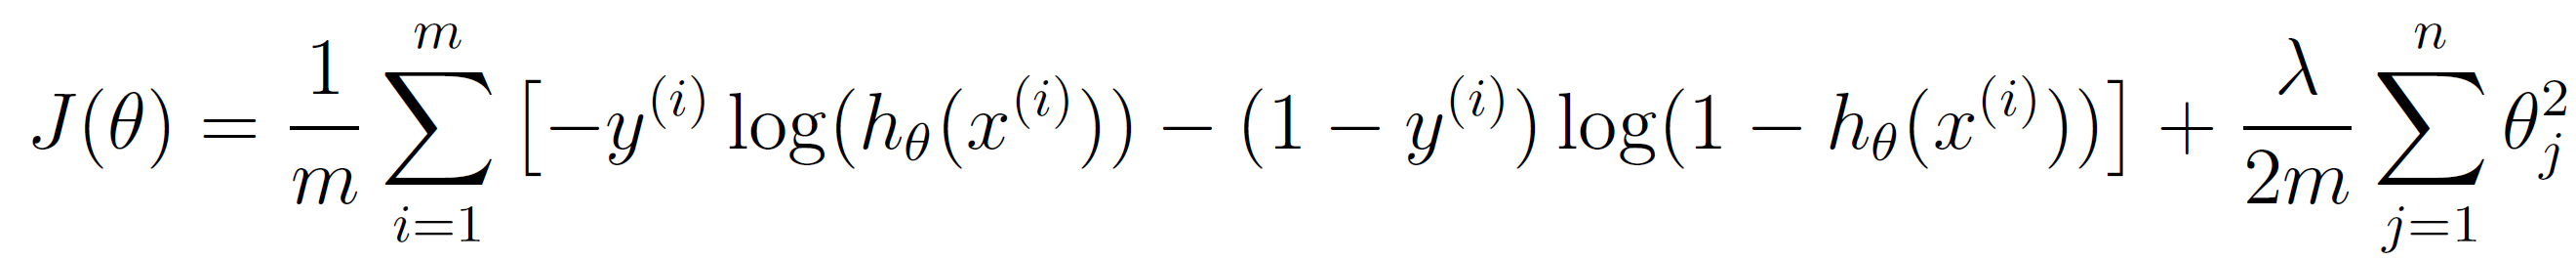

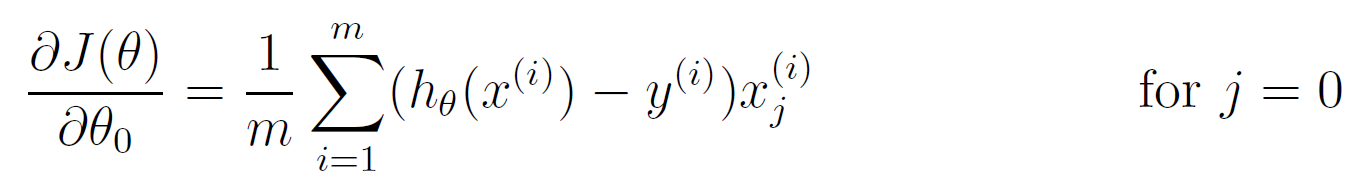

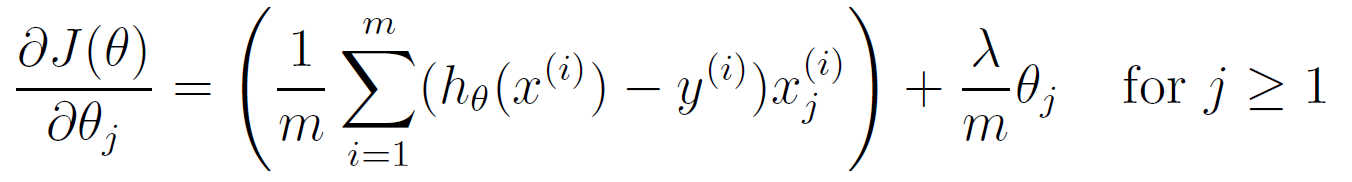

%====================================REG LOG COST FUNCTION=============================================%
function [J, grad] = costFunctionReg(theta, X, y, lambda)

m = length(y); % number of training examples
 
% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));
J = J + (lambda/(2*m)) * sum(theta(2:end).^2);

grad = (1/m) * (X' * (h - y));
grad(2:end) = grad(2:end) + (lambda/m) * theta(2:end);

end

%=====================================================================================================%


%==============SIGMOID FUNCTION===============%

function g = sigmoid(z)

g = zeros(size(z));
g = 1./(1+exp(-z)); %g = 1./(1+e.^(-z))

end

%=============================================%

%==============PREDICT FUNCTION===============%

function p = predict(theta, X)

m = size(X,1);
p = zeros(m, 1);

h = sigmoid(X*theta);
p(h>=0.5) = 1;

end

%=============================================%

function plotHistogram(data, plotTitle)
    % plotHistogram creates a histogram for the input data array with a title.
    % Inputs:
    %   - data: Array of numeric data to be visualized in the histogram
    %   - plotTitle: String for the title of the plot

    % Create the histogram
    histogram(data, 'NumBins', 30, 'FaceColor', 'blue', 'EdgeColor', 'black');

    % Customize the appearance
    xlabel('Data Values');
    ylabel('Frequency');
    title(plotTitle);
    grid on;
end